# Multi-Period Distributed Optimal Power Flow

## Temporally Brute-Forced, Spatially Distributed, Integer-Relaxed NLP.

clearVars = true;

localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    cd(strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep) )
    addpath(genpath('functions\'))
    latex_interpreter
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end
addDirectories; % adds rawDataFolder, latex_interpreter
rawDataFolder = "rawData";
clearVariables(clearVars);

start = tic;
verbose = false;
logging = true;
logging_Aeq_beq = false;
systemName = 'ieee123'

systemName = 'ieee123'

objFunction = "loss_min"

objFunction = "loss_min"

numAreas = 4

numAreas = 4

T = 5

T = 5

macroItrMax = 100; % Max no. of permissible iterations for optimizing an area
noBatteries = false;
alpha = 1e-3;
% gamma = 1e-1;
gamma = 1e0;
DER_percent = 100;
% Batt_percent = ~noBatteries*DER_percent;
Batt_percent = ~noBatteries * 100;
delta_t = 1.00; % one hour
displayTables = true;
displayNetworkGraphs = false;
displayActualBusNumbersInGraphs = false;
saveNetworkGraphPlots = false;
generateTextFilesForResults = true;
displaySimulationResultPlots = false;
saveSimulationResultPlots = false;
saveSCDPlots = false;

globalPVCoeff = 1.0;
[pvCoeffVals, lambdaVals, S_to_P_ratio_PV, ...
    S_to_P_ratio_Batt, costArray] = inputForecastData(rawDataFolder, T, globalPVCoeff);

V_min = 0.95;
V_max = 1.05;
etta_C = 0.95;
etta_D = 0.95;
soc_min = 0.30;
soc_max = 0.95;

if numAreas == 1
    copf = true;
    myfprintf(verbose, logging, "Centralized OPF it is.");
    simNatureString = "Centralized-OPF";
else
    copf = false;
    myfprintf(verbose, logging, "Perforiming Distributed OPF with %d Areas.", numAreas);
    simNatureString = "Spatially-Distributed-OPF";
end


if strcmp(systemName, "ieee123")
    N = 128;
    m = N-1;
else
    error("Unknown Power System")
end

actualBusNums = [1:36, 119, 126, 127, 117, 54:68, 122, 118, 37:53, 120, 125, 128, 69:116, 121, 123, 124]';
% N = max(actualBusNums);

if strcmp(objFunction, "loss_min")
    strObjectiveFunction = "Loss Minimization";
    suffixObj = "minLoss";
elseif strcmp(objFunction, "gen_cost")
    strObjectiveFunction = "Cost of Substation Power";
    suffixObj = "genCost";
else
    error("Objective Function NOT recognized.")
end

loggingLocationName = "logfiles/";

saveLocationFilename = strcat(loggingLocationName , systemName, "/numAreas_", num2str(numAreas), "/optimizationLogs.txt");
fileOpenedFlag = false;

systemDataFolder = strcat("rawData", filesep, systemName, filesep, "numAreas_", num2str(numAreas), filesep);

kVA_B = 1000; % base kVA
kV_B = 4.16/sqrt(3);  % 2.4018

a = [0.25 0.05]; %coefficient for correction step
chargeToPowerRatio = 4;

[CBMatrix, CBTable] = extractConnectionData(systemDataFolder);

numChildAreas = zeros(numAreas, 1);
numRelationships = length(CBTable.parentArea);
uniqueParents = unique(CBTable.parentArea);
numUniqueParents = length(uniqueParents);

[isLeaf, isRoot] = deal( ones(numAreas, 1) );
for relationshipNum = 1:numRelationships
    parAr = CBTable.parentArea(relationshipNum);
    isLeaf(parAr, 1) = 0;
    chAr = CBTable.childArea(relationshipNum);
    isRoot(chAr, 1) = 0;
    numChildAreas(parAr) = numChildAreas(parAr) + 1; %contains which area has how many children
end

sysInfo = struct();
sysInfo.N = N;
sysInfo.m = m;
sysInfo.nBatt = 0; % will be incremented later
sysInfo.nDER = 0; % will be incremented later
sysInfo.numRelationships = numRelationships;
sysInfo.numAreas = numAreas;
sysInfo.numChildAreas = numChildAreas; % An array of containing no. of 
sysInfo.actualBusNums = actualBusNums;

% child areas for each area
sysInfo.systemName = systemName;
sysInfo.isLeaf = isLeaf;
sysInfo.isRoot = isRoot;
sysInfo.kVA_B = kVA_B;
sysInfo.kV_B = kV_B;
sysInfo.Battery.chargeToPowerRatio = chargeToPowerRatio;
sysInfo.CBTable = CBTable;

% sysInfo.fbus = ?
% sysInfo.tbus = ?
% sysInfo.branchData = ?
sysInfo.DER_or_not = zeros(N, 1);
sysInfo.Batt_or_not = zeros(N, 1);
sysInfo.Q_C_Full = zeros(N, 1);
sysInfo.P_L_1toT = zeros(N, T);
sysInfo.P_L_Total_1toT = zeros(T, 1);
sysInfo.pD_Full_1toT = zeros(N, T);
sysInfo.pD_Total_1toT = zeros(T, 1);
sysInfo.qD_Full_1toT = zeros(N, T);
sysInfo.qD_Total_1toT = zeros(T, 1);
sysInfo.Pd_Full_1toT = zeros(N, T);
sysInfo.Pc_Full_1toT = zeros(N, T);
sysInfo.Pdc_Full_1toT = zeros(N, T);
sysInfo.Pd_Total_1toT = zeros(T, 1);
sysInfo.Pc_Total_1toT = zeros(T, 1);
sysInfo.Pdc_Total_1toT = zeros(T, 1);


% PLoss_allT_vs_macroItr = zeros(macroItrMax, 1);
% PLoss_1toT_vs_macroItr = zeros(T, macroItrMax);
% PSubs_allT_vs_macroItr = zeros(macroItrMax, 1);
% PSubs_1toT_vs_macroItr = zeros(T, macroItrMax);
% PSubsCost_allT_vs_macroItr = zeros(macroItrMax, 1);
% PSubsCost_1toT_vs_macroItr = zeros(T, macroItrMax);
[PLoss_allT_vs_macroItr, PSubs_allT_vs_macroItr, ...
    PSubsCost_allT_vs_macroItr, QSubs_allT_vs_macroItr] = deal(zeros(macroItrMax, 1));
[PLoss_1toT_vs_macroItr, PSubs_1toT_vs_macroItr, ...
    PSubsCost_1toT_vs_macroItr, QSubs_1toT_vs_macroItr] = deal(zeros(T, macroItrMax));

% y_allR_
sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
sysInfo.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
sysInfo.QSubs_allT_vs_macroItr = QSubs_allT_vs_macroItr;
sysInfo.QSubs_1toT_vs_macroItr = QSubs_1toT_vs_macroItr;


simInfo = struct();
if copf
    simInfo.simName = "MPCOPF";
else
    simInfo.simName = "MPDOPF";
end
simInfo.copf = copf;
simInfo.simNatureString = simNatureString;
simInfo.alpha = alpha;
simInfo.gamma = gamma;
simInfo.DER_percent = DER_percent;
simInfo.Batt_percent = Batt_percent;
battstring = strcat('pv_', num2str(DER_percent), '_batt_', num2str(Batt_percent));
simInfo.battstring = battstring;
simInfo.etta_C = etta_C;
simInfo.etta_D = etta_D;
simInfo.chargeToPowerRatio = chargeToPowerRatio;
simInfo.soc_min = soc_min;
simInfo.soc_max = soc_max;
simInfo.V_min = V_min;
simInfo.V_max = V_max;
simInfo.lambdaVals = lambdaVals;
simInfo.pvCoeffVals = pvCoeffVals;
simInfo.S_to_P_ratio_PV = S_to_P_ratio_PV;
simInfo.S_to_P_ratio_Batt = S_to_P_ratio_Batt;
simInfo.noBatteries = noBatteries;
simInfo.objFunction = objFunction;
simInfo.strObjectiveFunction = strObjectiveFunction;
simInfo.suffixObj = suffixObj;
simInfo.T = T;
if copf
    simInfo.alg.spatial = "CentralizedOPF";
else
    simInfo.alg.spatial = "ENApp";
end
simInfo.costArray = costArray;
simInfo.delta_t = delta_t;
simInfo.alg.temporal = "BruteForce";
simInfo.alg.macroItrMax = macroItrMax;
% stopping criterion
macroItrResidualTolerance = 0.001 ; % Tolerance

simInfo.alg.macroItrResidualTolerance = macroItrResidualTolerance;
simInfo.macroItrsCompleted = 0;
simInfo.alg.correctionStep = a;
simInfo.macroItr = 0;

simInfo.alg.microItrMax = 100;
simInfo.alg.tolfun = 1e-6;
simInfo.alg.stepTol = 1e-6;
simInfo.alg.constraintTol = 1e-6;
simInfo.alg.optimalityTol = 1e-6;

maxConnectingBusNum = max(CBTable.conBus_parentAreaTo);


#### Start with the algorithm

if logging && verbose
    error("Kindly specify ONLY one of the following arguments as true: verbose and logging.")
elseif logging && ~verbose
    fileOpenedFlag = true;
    fid = fopen(saveLocationFilename, 'w');
elseif ~logging
    logging = verbose;
    fid = 1;
else
    fid = 1;
end

myfprintf(true, fid, "A total of %d time-periods (of %d minutes each, so %.2f hours in total) " + ...
"will be run.\n", T, delta_t*60, delta_t*T);

myfprintf(logging, fid, "********Running Full OPF for the system.********\n"); %always true
keepRunningIterations = true;
time_dist = zeros(macroItrMax, numAreas);

maxResidual_vs_macroItr_allT = zeros(macroItrMax, 1);
v1_1 = 1.03^2*ones(numAreas, 1);
v1_1toT = repmat(v1_1, 1, T);

Se_iter = zeros(macroItrMax, numAreas, T);

% Se_iter = zeros(macroItrMax, m, numAreas, T);
V_iter = zeros(macroItrMax, N, numUniqueParents, T);
S12_allRelationships = CBTable.S_childArea;
S12_allRelationships_1toT = repmat(S12_allRelationships, 1, T);

S_parent_1toT = zeros(numAreas, T);
S_Areas_1toT = zeros(N, numAreas, T);
v_Areas_1toT = zeros(N, numAreas, T);
% v1_1toT_vs_macroItr = zeros(numAreas, T, macroItrMax);
v1_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
S12_1toT_vs_macroItr = zeros(numRelationships, T, macroItrMax);
Residuals_1toT_vs_macroItr = zeros(2*numRelationships, T, macroItrMax);

while keepRunningIterations
    for Area = 1:numAreas
    % for Area = 1
    % for Area = [2 3 1 4]
        macroItr = simInfo.macroItr;
        myfprintf(true, "Macro-iteration %d: Running OPF for Area %d.\n", macroItr+1, Area);

        v_parAr_1toT = v1_1toT(Area, 1:T);
        S_chArs_1toT = S12_allRelationships_1toT(CBTable.parentArea == Area, 1:T);

        if macroItr == 0
            areaInfo.Area = Area;
        else
            areaInfo = sysInfo.Area{Area};
        end

        [xVals_Area, sysInfo, simInfo, ...
            time_dist] = ...
            ...
            NL_OPF_dist2(sysInfo, simInfo, areaInfo, v_parAr_1toT, S_chArs_1toT, ...
            time_dist, 'verbose', verbose, 'saveToFile', true, 'logging', logging, ...
            'saveSCDPlots', saveSCDPlots);
        

Macro-iteration 1: Running OPF for Area 1.
Macro-iteration 1: Running OPF for Area 2.
Macro-iteration 1: Running OPF for Area 3.
Macro-iteration 1: Running OPF for Area 4.


Macro-iteration 2: Running OPF for Area 1.
Macro-iteration 2: Running OPF for Area 2.
Macro-iteration 2: Running OPF for Area 3.
Macro-iteration 2: Running OPF for Area 4.


Macro-iteration 3: Running OPF for Area 1.
Macro-iteration 3: Running OPF for Area 2.
Macro-iteration 3: Running OPF for Area 3.
Macro-iteration 3: Running OPF for Area 4.


Macro-iteration 4: Running OPF for Area 1.
Macro-iteration 4: Running OPF for Area 2.
Macro-iteration 4: Running OPF for Area 3.
Macro-iteration 4: Running OPF for Area 4.


Macro-iteration 5: Running OPF for Area 1.
Macro-iteration 5: Running OPF for Area 2.
Macro-iteration 5: Running OPF for Area 3.
Macro-iteration 5: Running OPF for Area 4.


        nVars1_Area = length(xVals_Area)/T;
        xVals_Area_1toT = reshape(xVals_Area, nVars1_Area, T);
        % macroItr = simInfo.macroItr;
        
        myfprintf(true, fid, "Current Macro-iteration %d: OPF for Area %d computed.\n", macroItr+1, Area)
        areaInfo = sysInfo.Area{Area};

        P_L_Area_1toT_kW = kVA_B*sum(areaInfo.P_L_Area_1toT);
        Q_L_Area_1toT_kW = kVA_B*sum(areaInfo.Q_L_Area_1toT);
        % myfprintf(true, "Current Macro-iteration %d: Total Load for Area %d is %4.4f kW + %4.4f kVAr.\n", macroItr+1, Area, P_L_Area_1toT_kW, Q_L_Area_1toT_kW);

        N_Area = areaInfo.N_Area;
        m_Area = areaInfo.m_Area;
        nDER_Area = areaInfo.nDER_Area;
        nBatt_Area = areaInfo.nBatt_Area;
        % indices_Pij = areaInfo.indices_Pij;
        P_Area_1toT = xVals_Area(areaInfo.indices_Pij); %m_Areax1
        Q_Area_1toT = xVals_Area(areaInfo.indices_Qij); %m_Areax1
        S_Area_1toT = complex(P_Area_1toT, Q_Area_1toT); %m_Areax1
        vAll_Area_1toT = xVals_Area(areaInfo.indices_vAllj); %N_Areax1
        V_Area_1toT = sqrt(vAll_Area_1toT);
        % fprintf("Printing out area %d before V_1toT added: macroItr (areaInfo) = %d", Area, macroItr)
        % disp(length(fieldnames(areaInfo)));
        areaInfo.V_Area_1toT = V_Area_1toT;
        % fprintf("Printing out area %d after V_1toT added: macroItr (areaInfo) = %d", Area, macroItr)
        % disp(length(fieldnames(areaInfo)));
        sysInfo.Area{Area} = areaInfo;
        % fprintf("Printing out sysInfo's memory of Area %d immediately after areaInfo inserted: macroItr = %d", Area, macroItr)
        % disp(length(fieldnames(sysInfo.Area{Area})));
        qD_Area_1toT = xVals_Area(areaInfo.indices_qDj);
        qD_AreaFull_1toT = sparseArrayFromDense(qD_Area_1toT, N_Area, areaInfo.busesWithDERs_Area);
        PSubs_Area_1toT = P_Area_1toT(1, 1:T);
        S_parent_1toT(Area, 1:T) = S_Area_1toT(1, 1:T);

        v_Areas_1toT(1:N_Area, Area, 1:T) = vAll_Area_1toT;
        S_Areas_1toT(1:m_Area, Area, 1:T) = S_Area_1toT;  % Storing all the S flow of the Area
        
        PLoss_allT_vs_macroItr(macroItr+1) = PLoss_allT_vs_macroItr(macroItr+1) + areaInfo.PLoss_allT;
        PLoss_1toT_vs_macroItr(1:T, macroItr+1) = PLoss_1toT_vs_macroItr(1:T, macroItr+1) + areaInfo.PLoss_1toT;
        
        if Area == 1
            PSubs_allT_vs_macroItr(macroItr+1) = areaInfo.PSubs_allT;
            PSubs_1toT_vs_macroItr(1:T, macroItr+1) = areaInfo.PSubs_1toT;
            PSubsCost_allT_vs_macroItr(macroItr+1) = areaInfo.PSubsCost_allT;
            PSubsCost_1toT_vs_macroItr(1:T, macroItr+1) = areaInfo.PSubsCost_1toT;
            QSubs_allT_vs_macroItr(macroItr+1) = areaInfo.QSubs_allT;
            QSubs_1toT_vs_macroItr(1:T, macroItr+1) = areaInfo.QSubs_1toT;
        end

        if macroItr == 0
            sysInfo.nDER = sysInfo.nDER + areaInfo.nDER_Area;
            sysInfo.nBatt = sysInfo.nBatt + areaInfo.nBatt_Area;
            sysInfo.DER_or_not(areaInfo.busesWithDERs_Actual) = 1;
            sysInfo.Batt_or_not(areaInfo.busesWithBatts_Actual) = 1;
        end
        

        % sysInfo.Area{Area} = areaInfo;
        
        sysInfo.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;  
        sysInfo.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
        sysInfo.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
        sysInfo.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
        sysInfo.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
        sysInfo.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
        sysInfo.QSubs_allT_vs_macroItr = QSubs_allT_vs_macroItr;
        sysInfo.QSubs_1toT_vs_macroItr = QSubs_1toT_vs_macroItr;
        % keyboard
    end
    
    % for i = 1:numAreas
        % fprintf("Printing out area 1 for no reason A: macroItr = %d", macroItr)
        % disp(length(fieldnames(sysInfo.Area{1})));
    % end

    myfprintf(true, "Macro-iteration %d: OPF's for all Areas completed. Checking for convergence.\n", macroItr+1);
    
    if macroItr == 0
        myfprintf(true, "Just collecting some mappings for DER and Battery Bus Indices")
        if DER_percent > 0 
            myfprintf(true, "Just collecting some mappings for DER Bus Indices")
            sysInfo.busesWithDERs = find(sysInfo.DER_or_not > 0);
            % keyboard
        end
        if Batt_percent > 0
            myfprintf(true, "Just collecting some mappings for Battery Bus Indices")
            sysInfo.busesWithBatts = find(sysInfo.Batt_or_not > 0);
        end

        for Area = 1:numAreas
            areaInfo = sysInfo.Area{Area};
            areaInfo.DERBusNums_Actual = findIndicesInArray(sysInfo.busesWithDERs, areaInfo.busesWithDERs_Actual);
            areaInfo.BattBusNums_Actual = findIndicesInArray(sysInfo.busesWithBatts, areaInfo.busesWithBatts_Actual);
            sysInfo.Area{Area} = areaInfo;
        end

    end

    % keyboard;
    if ~copf
        for relationshipNum = 1 : numRelationships
    
            parAr = CBTable.parentArea(relationshipNum);
            chAr = CBTable.childArea(relationshipNum);
            myfprintf(true, "Checking for convergence between parent Area %d and child Area %d\n", parAr, chAr);

            parentAreaConnectingBus = CBTable.conBus_parentAreaTo(relationshipNum);
            % S12_fromParent_1toT = reshape(S_Areas_1toT(parentAreaConnectingBus - 1, parAr, 1:T), 1, T);
            S12_intoChild_1toT = reshape(S_Areas_1toT(1, chAr, 1:T), 1, T);
            if macroItr+1 > 1 % not macroItr == 0
                S12_intoChild_1toT_mIm1 = S12_1toT_vs_macroItr(relationshipNum, 1:T, macroItr);
            else
                S12_intoChild_1toT_mIm1 = 0;
            end
            
            delta_S12_1toT = S12_intoChild_1toT - S12_intoChild_1toT_mIm1;
            % S12_intoChild_1toT = reshape(S_parent_1toT(chAr, 1:T), 1, T);
    
            % delta_S12_1toT = S12_fromParent_1toT - S12_intoChild_1toT;
    
            v_parentSide_1toT = reshape(v_Areas_1toT(parentAreaConnectingBus, parAr, 1:T), 1, T);
            % v_childSide_1toT = v1_1toT(chAr, 1:T);
    
            v1_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = v_parentSide_1toT;
            S12_1toT_vs_macroItr(relationshipNum, 1:T, macroItr+1) = S12_intoChild_1toT;
            
            if macroItr+1 > 1 % not macroItr == 0
                v1_parentSide_1toT_mIm1 = v1_1toT_vs_macroItr(relationshipNum, 1:T, macroItr);
            else
                v1_parentSide_1toT_mIm1 = v1_1(1);
            end
            % delta_v_1toT = v_parentSide_1toT - v_childSide_1toT;
            delta_v_1toT = v_parentSide_1toT - v1_parentSide_1toT_mIm1;
            Residual_Area_1toT = reshape([delta_S12_1toT; delta_v_1toT], 2*T, 1);
            
            [currentMaxResidual_1toT, lin_idx] = max(abs(Residual_Area_1toT));

            row = lin_idx;
            myfprintf(true, "Macro-iteration %d: Current Biggest Residual is %d at index %d.\n", macroItr+1, currentMaxResidual_1toT, row);

            
            if currentMaxResidual_1toT > maxResidual_vs_macroItr_allT(macroItr+1)
                maxResidual_vs_macroItr_allT(macroItr+1) = currentMaxResidual_1toT;
                myfprintf(true, "It is even bigger than the previous biggest residual.\n");
            end
            
            % fprintf("Printing out area 1 for no reason B: macroItr = %d", macroItr)
            % disp(length(fieldnames(sysInfo.Area{1})));
        end
        
        myfprintf(true, "Macro-iteration %d: Checking for convergence among all connected areas completed.\n", macroItr+1);
        
        if macroItr == macroItrMax - 1
            error("Didn't converge even after %d macro-iterations, terminating.\n", macroItrMax);
    
        elseif currentMaxResidual_1toT < macroItrResidualTolerance
            myfprintf(true, "MPOPF for Horizon T = %d Converged in %d macro-iterations!\n", T, macroItr+1);
            keepRunningIterations = false;
            maxResidual_vs_macroItr_allT = maxResidual_vs_macroItr_allT(1:macroItr+1);
    
        else
            myfprintf(true, "MPOPF for Horizon T = %d , Still yet to converge after %d macro-iterations, continuing.\n", T, macroItr+1)
            %Communication-
            myfprintf(true, "Since there is still a difference in boundary variables, " + ...
                "let's exchange boundary variables.\n")
            
            % fprintf("Printing out area 1 for no reason C: macroItr = %d", macroItr)
            % disp(length(fieldnames(sysInfo.Area{1})));

            for relationshipNum = 1:numRelationships
                parAr = CBTable.parentArea(relationshipNum);
                chAr = CBTable.childArea(relationshipNum);
                myfprintf(true, "Communicating between parent Area %d and child Area %d\n", parAr, chAr);

                busParTo = CBTable.conBus_parentAreaTo(relationshipNum);

                areaInfo_par = sysInfo.Area{parAr};
                areaInfo_ch = sysInfo.Area{chAr};
    
                
                V_iter(macroItr+1, busParTo, parAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T) ;

                Se_iter(macroItr+1, chAr, 1:T) = S_parent_1toT(chAr, 1:T);
    
                if macroItr >= 2
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = a(2)*reshape(V_iter(macroItr, busParTo, parAr, 1:T), 1, T) + ...
                        a(1)*reshape(V_iter(macroItr+1, busParTo, parAr, 1:T), 1, T) + ...
                        (1-sum(a))*reshape(v_Areas_1toT(busParTo, parAr, 1:T), 1, T);
                    % disp(v1_1toT(char, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)

                    S12_allRelationships_1toT(relationshipNum, 1:T) = a(2)*reshape(Se_iter(macroItr-1, chAr, 1:T), 1, T)+...
                        a(1)*reshape(Se_iter(macroItr, chAr, 1:T), 1, T)+...
                        (1-sum(a))*S_parent_1toT(chAr, 1:T);
                    % disp(S12_allRelationships_1toT(relationshipNum, 1:T));
                else
                    myfprintf(true, "***Macro-iteration %d Communication Voltage:****\n", macroItr+1)
                    v1_1toT(chAr, 1:T) = v_Areas_1toT(busParTo, parAr, 1:T);
                    % disp(v1_1toT(chAr, 1:T))

                    myfprintf(true, "***Macro-iteration %d Communication Power:****\n", macroItr+1)
                    S12_allRelationships_1toT(relationshipNum, 1:T) = S_parent_1toT(chAr, 1:T);
                    % disp(S12_allRelationships_1toT(relationshipNum, 1:T));

    
                end
                
                % fprintf("Printing out area 1 for no reason D: macroItr = %d", macroItr)
                % disp(length(fieldnames(sysInfo.Area{1})));

            end

            simInfo.macroItr = macroItr + 1;

        end

        
    else
        keepRunningIterations = false;
        myfprintf(verbose, "Centralized MPOPF for %d Horizons ended.\n", T);
    end

end

Macro-iteration 1: OPF's for all Areas completed. Checking for convergence.


Just collecting some mappings for DER and Battery Bus Indices

Just collecting some mappings for DER Bus Indices

Just collecting some mappings for Battery Bus Indices

Checking for convergence between parent Area 1 and child Area 2


Macro-iteration 1: Current Biggest Residual is 1.288326e-01 at index 7.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


Macro-iteration 1: Current Biggest Residual is 1.729236e-01 at index 3.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 2 and child Area 4


Macro-iteration 1: Current Biggest Residual is 3.245076e-01 at index 1.


It is even bigger than the previous biggest residual.


Macro-iteration 1: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 5 , Still yet to converge after 1 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 1 Communication Voltage:****


***Macro-iteration 1 Communication Power:****


Communicating between parent Area 1 and child Area 3


***Macro-iteration 1 Communication Voltage:****


***Macro-iteration 1 Communication Power:****


Communicating between parent Area 2 and child Area 4


***Macro-iteration 1 Communication Voltage:****


***Macro-iteration 1 Communication Power:****


Macro-iteration 2: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


Macro-iteration 2: Current Biggest Residual is 3.125206e-01 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


Macro-iteration 2: Current Biggest Residual is 1.735420e-02 at index 8.


Checking for convergence between parent Area 2 and child Area 4


Macro-iteration 2: Current Biggest Residual is 9.830420e-03 at index 8.


Macro-iteration 2: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 5 , Still yet to converge after 2 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 2 Communication Voltage:****


***Macro-iteration 2 Communication Power:****


Communicating between parent Area 1 and child Area 3


***Macro-iteration 2 Communication Voltage:****


***Macro-iteration 2 Communication Power:****


Communicating between parent Area 2 and child Area 4


***Macro-iteration 2 Communication Voltage:****


***Macro-iteration 2 Communication Power:****


Macro-iteration 3: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


Macro-iteration 3: Current Biggest Residual is 4.882980e-03 at index 10.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


Macro-iteration 3: Current Biggest Residual is 4.874513e-03 at index 10.


Checking for convergence between parent Area 2 and child Area 4


Macro-iteration 3: Current Biggest Residual is 1.245600e-02 at index 8.


It is even bigger than the previous biggest residual.


Macro-iteration 3: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 5 , Still yet to converge after 3 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 3 Communication Voltage:****


***Macro-iteration 3 Communication Power:****


Communicating between parent Area 1 and child Area 3


***Macro-iteration 3 Communication Voltage:****


***Macro-iteration 3 Communication Power:****


Communicating between parent Area 2 and child Area 4


***Macro-iteration 3 Communication Voltage:****


***Macro-iteration 3 Communication Power:****


Macro-iteration 4: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


Macro-iteration 4: Current Biggest Residual is 2.795951e-04 at index 7.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


Macro-iteration 4: Current Biggest Residual is 2.464844e-04 at index 4.


Checking for convergence between parent Area 2 and child Area 4


Macro-iteration 4: Current Biggest Residual is 4.638683e-03 at index 10.


It is even bigger than the previous biggest residual.


Macro-iteration 4: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 5 , Still yet to converge after 4 macro-iterations, continuing.


Since there is still a difference in boundary variables, let's exchange boundary variables.


Communicating between parent Area 1 and child Area 2


***Macro-iteration 4 Communication Voltage:****


***Macro-iteration 4 Communication Power:****


Communicating between parent Area 1 and child Area 3


***Macro-iteration 4 Communication Voltage:****


***Macro-iteration 4 Communication Power:****


Communicating between parent Area 2 and child Area 4


***Macro-iteration 4 Communication Voltage:****


***Macro-iteration 4 Communication Power:****


Macro-iteration 5: OPF's for all Areas completed. Checking for convergence.


Checking for convergence between parent Area 1 and child Area 2


Macro-iteration 5: Current Biggest Residual is 3.304344e-04 at index 1.


It is even bigger than the previous biggest residual.


Checking for convergence between parent Area 1 and child Area 3


Macro-iteration 5: Current Biggest Residual is 2.485030e-04 at index 10.


Checking for convergence between parent Area 2 and child Area 4


Macro-iteration 5: Current Biggest Residual is 5.894137e-05 at index 3.


Macro-iteration 5: Checking for convergence among all connected areas completed.


MPOPF for Horizon T = 5 Converged in 5 macro-iterations!


% keyboard;
sysInfo = truncateSysInfo(sysInfo, macroItr);
% keyboard;
% if ~copf 
    sysInfo = collectCentralizedInfo(sysInfo, simInfo);
% end

% saveSCDPlots = true
if Batt_percent > 0 && saveSCDPlots
    for Area = 1:numAreas
        areaInfo = sysInfo.Area{Area};
        xValsArea_1toT = areaInfo.xvals;
        checkForSCD(sysInfo, simInfo, areaInfo, T, xValsArea_1toT, 'savePlots', true);
    end
end

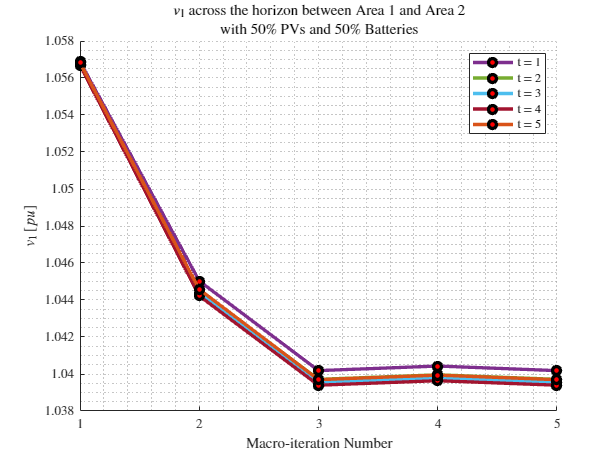

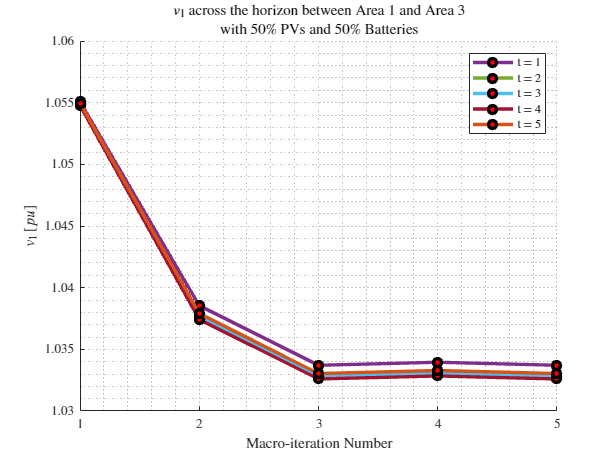

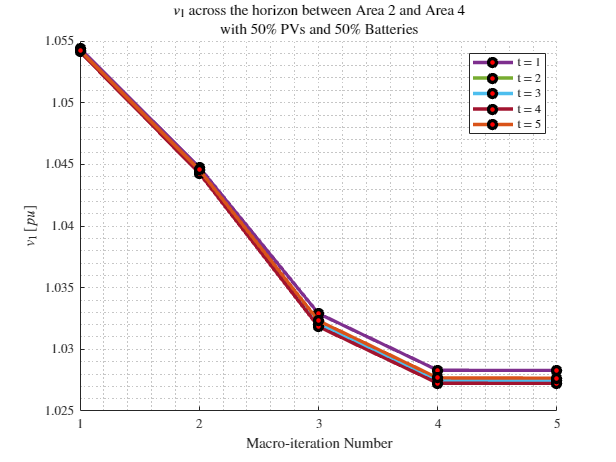

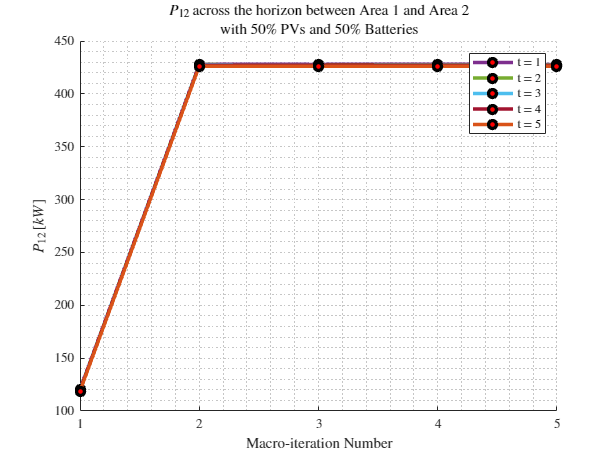

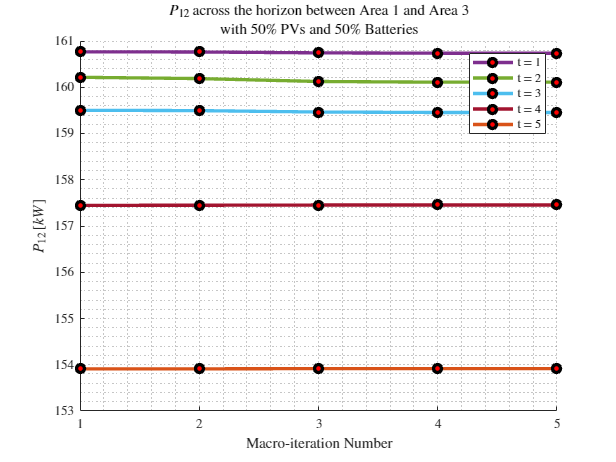

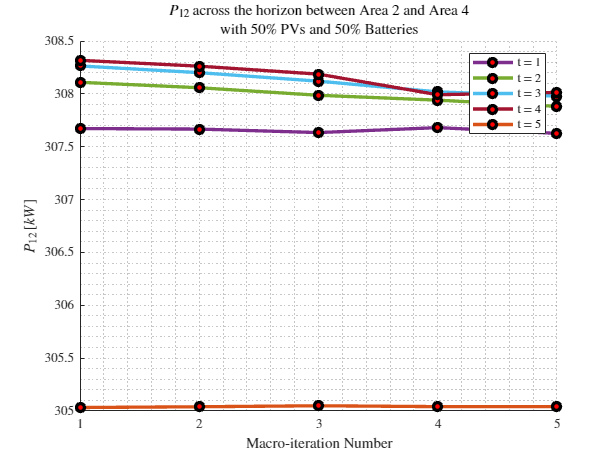

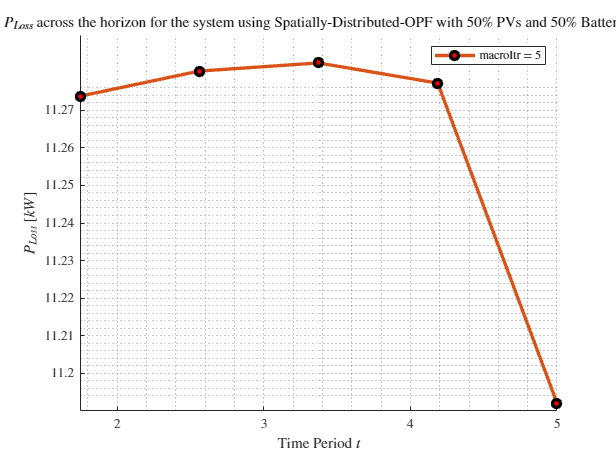

V_iter = V_iter(1:macroItr+1, :, :, :);
PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr(1:macroItr+1);
PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr(:, 1:macroItr+1);
PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr(1:macroItr+1);
PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr(:, 1:macroItr+1);
PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr(1:macroItr+1);
PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr(:, 1:macroItr+1);
v1_1toT_vs_macroItr = v1_1toT_vs_macroItr(:, :, 1:macroItr+1);
S12_1toT_vs_macroItr = S12_1toT_vs_macroItr(:, :, 1:macroItr+1);
P12_1toT_vs_macroItr = real(S12_1toT_vs_macroItr);
time_dist = time_dist(1:macroItr+1, :);

results = struct();
results.PLoss_allT_vs_macroItr = PLoss_allT_vs_macroItr;
results.PLoss_1toT_vs_macroItr = PLoss_1toT_vs_macroItr;
results.PSubs_allT_vs_macroItr = PSubs_allT_vs_macroItr;
results.PSubs_1toT_vs_macroItr = PSubs_1toT_vs_macroItr;
results.PSubsCost_allT_vs_macroItr = PSubsCost_allT_vs_macroItr;
results.PSubsCost_1toT_vs_macroItr = PSubsCost_1toT_vs_macroItr;
results.QSubs_allT_vs_macroItr = QSubs_allT_vs_macroItr;
results.QSubs_1toT_vs_macroItr = QSubs_1toT_vs_macroItr;
results.v1_1toT_vs_macroItr = v1_1toT_vs_macroItr;
results.S12_1toT_vs_macroItr = S12_1toT_vs_macroItr;


results.P12_1toT_vs_macroItr = P12_1toT_vs_macroItr;

results.PLoss_allT = PLoss_allT_vs_macroItr(macroItr+1);
results.PLoss_1toT = PLoss_1toT_vs_macroItr(1:T, macroItr+1);
results.PSubs_allT = PSubs_allT_vs_macroItr(macroItr+1);
results.PSubs_1toT = PSubs_1toT_vs_macroItr(1:T, macroItr+1);
results.PSubsCost_allT = PSubsCost_allT_vs_macroItr(macroItr+1);
results.PSubsCost_1toT = PSubsCost_1toT_vs_macroItr(1:T, macroItr+1);
results.QSubs_allT = QSubs_allT_vs_macroItr(macroItr+1);
results.QSubs_1toT = QSubs_1toT_vs_macroItr(1:T, macroItr+1);

results.simInfo = simInfo;
results.sysInfo = sysInfo;
% plot_relationships_over_time(results, simInfo, sysInfo)
plot_simulation_results(results)

grandTotalTime = toc(start)

grandTotalTime = 1.2005e+03

    
lineLoss_kW_allT = 0;
lineLoss_kW_1toT = zeros(T, 1);

for areaNum = 1:numAreas
    areaInfo = sysInfo.Area{areaNum};
    lineLoss_Area_kW_1toT = areaInfo.PLoss_1toT * kVA_B;
    lineLoss_kW_1toT = lineLoss_kW_1toT + lineLoss_Area_kW_1toT;
    lineLoss_Area_kW_allT = areaInfo.PLoss_allT * kVA_B;
    lineLoss_kW_allT = lineLoss_kW_allT + lineLoss_Area_kW_allT;
end
area1Info = sysInfo.Area{1};
genCost_dollars_1toT = area1Info.PSubsCost_1toT * 1e-2;

% substationPower_kW_1toT = area1Info.P_Area_1toT(1, :)*kVA_B;
% substationPower_kW_1toT = sysInfo.PSubs_1toT_vs_macroItr(1:T, macroItr+1) * kVA_B;
substationPower_kW_1toT = sysInfo.PSubs_1toT * kVA_B;
substationPower_kVAr_1toT = sysInfo.QSubs_1toT * kVA_B;

maxTimes_vs_macroItr = max(time_dist, [], 2);
time_if_parallel = sum(maxTimes_vs_macroItr);
time_if_serial = sum(sum(time_dist));

if ~copf
    simNatureStringFull = strcat(simNatureString, " with ", num2str(numAreas), " Areas.");
else
    simNatureStringFull = simNatureString;
end

vald = struct();
vald.res = results;

% if copf
    % vald.loadShape = lambdaVals;
    vald.loadShape = sysInfo.loadShape;

    % vald.loadShapePV = pvCoeffVals;
    vald.loadShapePV = sysInfo.loadShapePV;
    % vald.busesWithDERs_Area = area1Info.busesWithDERs_Area;
    % vald.busesWithDERs = area1Info.busesWithDERs_Area;
    vald.busesWithDERs = sysInfo.busesWithDERs;
    % vald.Pmpp_AreaFull = area1Info.Pmpp_Area;
    % vald.Pmpp_Full = area1Info.Pmpp_Area;
    

    % vald.Pmpp_Area = area1Info.Pmpp_Area(vald.busesWithDERs_Area);
    % vald.Pmpp = area1Info.Pmpp_Area(vald.busesWithDERs);
    vald.Pmpp = sysInfo.Pmpp;

    % vald.Sder_AreaFull = area1Info.S_der_Area;
    % vald.Sder_Full = area1Info.S_der_Area;
    


    % vald.V_copf = V_Area_1toT;
    % vald.V_1toT = V_Area_1toT;
    vald.V_1toT = sysInfo.V_1toT;
    % vald.pL_AreaFull_1toT = area1Info.P_L_Area_1toT;
    % vald.pL_Full_1toT = area1Info.P_L_Area_1toT;

    % pLTotal_kW_1toT = sum(vald.pL_AreaFull_1toT)*kVA_B;
    % pLTotal_kW_1toT = sum(vald.pL_Full_1toT)*kVA_B;
    pLTotal_kW_1toT = sum(sysInfo.P_L_1toT)*kVA_B;
    % vald.qL_AreaFull_1toT = area1Info.Q_L_Area_1toT;
    % vald.qL_Full_1toT = area1Info.Q_L_Area_1toT;

    % qLTotal_kVAr_1toT = sum(vald.qL_AreaFull_1toT)*kVA_B;
    % qLTotal_kVAr_1toT = sum(vald.qL_Full_1toT)*kVA_B;
    qLTotal_kVAr_1toT = sum(sysInfo.Q_L_1toT)*kVA_B;
    
    % vald.pD_AreaFull_1toT = area1Info.P_der_Area_1toT;
    % pD_AreaFull_1toT = area1Info.P_der_Area_1toT;
    % pD_Full_1toT = area1Info.P_der_Area_1toT;

    % vald.pD_AreaFull_1toT = pD_AreaFull_1toT;
    % vald.pD_Full_1toT = pD_Full_1toT;

    % pDTotal_kW_1toT = sum(vald.pD_AreaFull_1toT)*kVA_B;
    % pDTotal_kW_1toT = sum(vald.pD_Full_1toT)*kVA_B;
    pDTotal_kW_1toT = sum(sysInfo.pD_1toT)*kVA_B;
    
    % vald.qD_AreaFull_1toT = qD_AreaFull_1toT;
    % vald.qD_Full_1toT = qD_Full_1toT;

    % busesWithDERs_Area = area1Info.busesWithDERs_Area;
    % busesWithDERs = area1Info.busesWithDERs_Area;
    busesWithDERs = sysInfo.busesWithDERs;

    % qD_onlyBusesWithDERs_1toT = qD_AreaFull_1toT(busesWithDERs_Area, 1:T);
    % qD_onlyBusesWithDERs_1toT = qD_Full_1toT(busesWithDERs, 1:T);
    % qD_1toT = areaInfo.qD_Area_1toT;

    % qD_onlyBusesWithDERs_1toT = qD_1toT;
    
    % pD_onlyBusesWithDERs_1toT = pD_AreaFull_1toT(busesWithDERs_Area, 1:T);
    % pD_onlyBusesWithDERs_1toT = pD_Full_1toT(busesWithDERs, 1:T);

    % vald.pD_Area_1toT = pD_onlyBusesWithDERs_1toT;
    % vald.pD_1toT = pD_onlyBusesWithDERs_1toT;
    vald.pD_1toT = sysInfo.pD_1toT;

    % vald.qD_Area_1toT = qD_onlyBusesWithDERs_1toT;
    % vald.qD_1toT = qD_onlyBusesWithDERs_1toT;
    vald.qD_1toT = sysInfo.qD_1toT;

    % Sder_AreaFull = area1Info.S_der_Area;
    % Sder_Full = area1Info.S_der_Area;

    % Sder_onlyBusesWithDERs = Sder_AreaFull(busesWithDERs_Area);
    % Sder_onlyBusesWithDERs = Sder_Full(busesWithDERs);

    % vald.Sder_Area = Sder_onlyBusesWithDERs;
    % vald.Sder = Sder_onlyBusesWithDERs;
    vald.Sder = sysInfo.Sder;

    % qDTotal_kVAr_1toT = sum(vald.qD_AreaFull_1toT)*kVA_B;
    % qDTotal_kVAr_1toT = sum(vald.qD_Full_1toT)*kVA_B;
    qDTotal_kVAr_1toT = sum(vald.qD_1toT)*kVA_B;
    % vald.qC_AreaFull = area1Info.Q_C_Area;
    % vald.qC_Full = area1Info.Q_C_Area;
    vald.qC_Full = sysInfo.Q_C_Full;

    % qCTotal_kVAr_1toT = repmat(sum(vald.qC_AreaFull), 1, T)*kVA_B;
    qCTotal_kVAr_1toT = repmat(sum(vald.qC_Full), 1, T)*kVA_B;

    % vald.busesWithBatt_Area = area1Info.busesWithBatts_Area;
    % vald.busesWithBatts = area1Info.busesWithBatts_Area;
    vald.busesWithBatts = sysInfo.busesWithBatts;

    % vald.S_battMax_Area = area1Info.S_onlyBattBusesMax_Area; % Actually this has 128 elements, so is 'Full'
    % vald.S_battRated = area1Info.S_onlyBattBusesMax_Area; % Actually this has 128 elements, so is 'Full'
    vald.S_battRated = sysInfo.Sbatt;
    % vald.Pd_Area_1toT = area1Info.Pd_Area_1toT;
    % vald.Pd_1toT = area1Info.Pd_Area_1toT;
    vald.Pd_1toT = sysInfo.Pd_1toT;

    % vald.P_battMax_Area = area1Info.P_onlyBattBusesMax_Area;
    % vald.P_battRated = area1Info.P_onlyBattBusesMax_Area;
    vald.P_battRated = sysInfo.Pbatt;

    % PdTotal_kW_1toT = sum(vald.Pd_Area_1toT)*kVA_B;
    PdTotal_kW_1toT = sum(vald.Pd_1toT)*kVA_B;

    % vald.Pc_Area_1toT = area1Info.Pc_Area_1toT;
    % vald.Pc_1toT = area1Info.Pc_Area_1toT;
    vald.Pc_1toT = sysInfo.Pc_1toT;

    % PcTotal_kW_1toT = sum(vald.Pc_Area_1toT)*kVA_B;
    PcTotal_kW_1toT = sum(vald.Pc_1toT)*kVA_B;

    PdcTotal_kW_1toT = PdTotal_kW_1toT - PcTotal_kW_1toT;

    % vald.B_Area_1toT = area1Info.B_Area_1toT;
    % vald.B_1toT = area1Info.B_Area_1toT;
    vald.B_1toT = sysInfo.B_1toT;

    % BTotal_kWh_1toTh = sum(vald.B_Area_1toT)*kVA_B;
    BTotal_kWh_1toTh = sum(vald.B_1toT)*kVA_B;

    % vald.B0_Area = area1Info.B0Vals_pu_Area;
    % vald.B0 = area1Info.B0Vals_pu_Area;
    vald.B0 = sysInfo.B0;

    % vald.qB_Area_1toT = area1Info.qB_Area_1toT;
    % vald.qB_1toT = area1Info.qB_Area_1toT;
    vald.qB_1toT = sysInfo.qB_1toT;

    % qBTotal_kVAr_1toT = sum(vald.qB_Area_1toT)*kVA_B;
    qBTotal_kVAr_1toT = sum(vald.qB_1toT)*kVA_B;

    pTotal_kW_1toT = PdTotal_kW_1toT + pDTotal_kW_1toT - PcTotal_kW_1toT;
    qTotal_kVAr_1toT = qDTotal_kVAr_1toT + qBTotal_kVAr_1toT + qCTotal_kVAr_1toT;
    
    % vald.nDER_Area = area1Info.nDER_Area;
    % vald.nDER = area1Info.nDER_Area;
    vald.nDER = sysInfo.nDER;

    % vald.nBatt_Area = area1Info.nBatt_Area;
    % vald.nBatt = area1Info.nBatt_Area;
    vald.nBatt = sysInfo.nBatt;

    vald.simInfo = simInfo;
% end

disp('------------------------------------------------------------')

------------------------------------------------------------


disp(['Machine ID: ', getenv("COMPUTERNAME")])

Machine ID: ETRL204-ARYAN


disp(['Horizon Duration: ', num2str(T)])

Horizon Duration: 5


disp(['Nature of Simulation: ', simNatureStringFull])

    "Nature of Simulation: "    "Spatially-Distributed-OPF with 4 Areas."



disp(['GED Configuruation: ', battstring])

GED Configuruation: pv_50_batt_50


for t = 1:T
    disp('-----------------------------')
    disp(['Hour: ', num2str(t)])
    disp(['Line Loss: ', num2str(lineLoss_kW_1toT(t)),' kW'])                       
    disp(['Substation Power: ', num2str(substationPower_kW_1toT(t)),' kW + ', num2str(substationPower_kVAr_1toT(t)), ' kVAr'])
    disp(['Total Load: ', num2str(pLTotal_kW_1toT(t)), ' kW + ', num2str(qLTotal_kVAr_1toT(t)), ' kVAr'])
    disp(['Total Generation: ', num2str(pTotal_kW_1toT(t)), ' kW + ', num2str(qTotal_kVAr_1toT(t)), ' kVAr' ])
    disp(['Total PV Generation: ', num2str(pDTotal_kW_1toT(t)), ' kW + ', num2str(qDTotal_kVAr_1toT(t)), ' kVAr'])
    disp(['Total Battery Generation: ', num2str(PdcTotal_kW_1toT(t)), ' kW + ', num2str(qBTotal_kVAr_1toT(t)), ' kVAr'])
    disp(['Total Static Capacitor Reactive Power Generation: ', num2str(qCTotal_kVAr_1toT(t)), ' kVAr'])
    % disp(['Total Reactive Power Generation: ', num2str(qTotal_kVAr_1toT(t)), ' kVAr'])
    disp(['Substation Power Cost: ', num2str(genCost_dollars_1toT(t)), ' $'])
end

-----------------------------


Hour: 1


Line Loss: 11.2737 kW


Substation Power: 733.4691 kW + 83.7356 kVAr


Total Load: 872.3977 kW + 480.009 kVAr


Total Generation: 150.5178 kW + 418.792 kVAr


Total PV Generation: 94.7774 kW + 34.396 kVAr


Total Battery Generation: 55.7405 kW + 34.396 kVAr


Total Static Capacitor Reactive Power Generation: 350 kVAr


Substation Power Cost: 37.4069 $


-----------------------------


Hour: 2


Line Loss: 11.2804 kW


Substation Power: 733.1547 kW + 94.1275 kVAr


Total Load: 903.8041 kW + 497.2893 kVAr


Total Generation: 182.1275 kW + 425.7269 kVAr


Total PV Generation: 151.6438 kW + 37.8635 kVAr


Total Battery Generation: 30.4837 kW + 37.8635 kVAr


Total Static Capacitor Reactive Power Generation: 350 kVAr


Substation Power Cost: 31.5257 $


-----------------------------


Hour: 3


Line Loss: 11.2826 kW


Substation Power: 732.9732 kW + 97.8585 kVAr


Total Load: 915.436 kW + 503.6894 kVAr


Total Generation: 193.8785 kW + 428.4046 kVAr


Total PV Generation: 170.5993 kW + 39.2023 kVAr


Total Battery Generation: 23.2792 kW + 39.2024 kVAr


Total Static Capacitor Reactive Power Generation: 350 kVAr


Substation Power Cost: 25.6541 $


-----------------------------


Hour: 4


Line Loss: 11.2772 kW


Substation Power: 732.779 kW + 101.2781 kVAr


Total Load: 925.9048 kW + 509.4496 kVAr


Total Generation: 204.3831 kW + 430.6914 kVAr


Total PV Generation: 189.5547 kW + 40.3457 kVAr


Total Battery Generation: 14.8284 kW + 40.3457 kVAr


Total Static Capacitor Reactive Power Generation: 350 kVAr


Substation Power Cost: 20.5178 $


-----------------------------


Hour: 5


Line Loss: 11.1921 kW


Substation Power: 730.6866 kW + 95.8318 kVAr


Total Load: 909.6201 kW + 500.4894 kVAr


Total Generation: 190.0898 kW + 427.0395 kVAr


Total PV Generation: 189.5547 kW + 38.5215 kVAr


Total Battery Generation: 0.53509 kW + 38.5181 kVAr


Total Static Capacitor Reactive Power Generation: 350 kVAr


Substation Power Cost: 20.4592 $


disp('------------------------------------------------------------')

------------------------------------------------------------


disp(['Number of Macro-Iterations: ', num2str(macroItr+1)])

Number of Macro-Iterations: 5


disp(['Simulation Time: ', num2str(grandTotalTime), ' s'])

Simulation Time: 1200.5302 s


disp(['Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s'])

Time to solve with sequential (non-parallel) computation: 1182.8739 s


disp(['Time to solve if OPF computation paralellized: ', num2str(time_if_parallel), ' s'])

Time to solve if OPF computation paralellized: 823.3414 s


disp('------------------------------------------------------------')

------------------------------------------------------------


% Assuming sysInfo, numAreas, T, and noBatteries are already defined in your workspace

% Construct the folder and file names
folderName = fullfile('processedData', sysInfo.systemName, strcat('numAreas_', num2str(numAreas), "/"));
prefixName = strcat(folderName, strcat('Horizon_', num2str(T)));

% Construct the full path for the TXT file
systemsSolutionName_fval = strcat(prefixName, "_", getenv('COMPUTERNAME'), '_results_', battstring, '.txt');

% Open the file for writing
fileID = fopen(systemsSolutionName_fval, 'w');

% Check if the file was opened successfully
if fileID == -1
    error('Failed to open file for writing.');
end

% Write the results to the file
fprintf(fileID, '------------------------------------------------------------\n');
fprintf(fileID, 'Machine ID: %s\n', getenv("COMPUTERNAME"));
fprintf(fileID, 'Horizon Duration: %d\n', T);
fprintf(fileID, 'Nature of Simulation: %s\n', simNatureStringFull);
fprintf(fileID, 'Line Loss: %.2f kW\n', lineLoss_kW_allT);                       
fprintf(fileID, 'Substation Power: %.2f kW\n', substationPower_kW_1toT);
fprintf(fileID, 'Substation Power Cost: %.3f $\n', genCost_dollars_1toT);
fprintf(fileID, 'Total Real Load: %.2f kW\n', pLTotal_kW_1toT);                       
fprintf(fileID, 'Total Reactive Load: %.2f kVAr\n', qLTotal_kVAr_1toT);
fprintf(fileID, 'Total PV Real Power Generation: %.2f kW\n', pDTotal_kW_1toT);
fprintf(fileID, 'Total PV Reactive Power Generation: %.2f kVAr\n', qDTotal_kVAr_1toT);
fprintf(fileID, 'Number of Macro-Iterations: %d\n', macroItr+1);
fprintf(fileID, 'Simulation Time: %.2f s\n', grandTotalTime);
fprintf(fileID, strcat('Time to solve with sequential (non-parallel) computation: ', num2str(time_if_serial), ' s\n'));
fprintf(fileID, 'Time to Solve if OPF computation parallelized: %.2f s\n', time_if_parallel);
fprintf(fileID, '------------------------------------------------------------\n');

% Close the file
fclose(fileID);

% Display a message indicating that the results were saved
disp(['Results saved to ', systemsSolutionName_fval]);

    "Results saved to "    "processedData\ieee123\numAreas_4\Horizon_5_ETRL204-ARYAN_results_pv_50_batt_50.txt"

